# BME3053 Final Project  

Team name: LCR

Group Members: Reuben Abraham, Christian Knuth, Laura Reis Neves

Course: BME 3053C Computer Applications for BME

Term: Fall 2023

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: reisneves.la@ufl.edu, 

December 6, 2023

**Step 1.** Read image with function xx.

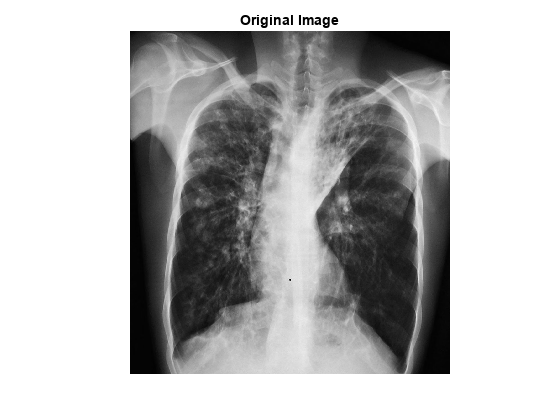

I=input('Which image needs to be analyzed? (Place '' around filename) '); % Prompt user to select image needed. 
img = imread(I);   % Reads image and stores it in a variable
imshow(img);
title('Original Image');

**Step 2.** Resize image to a standard scale, 1000 x 1000.

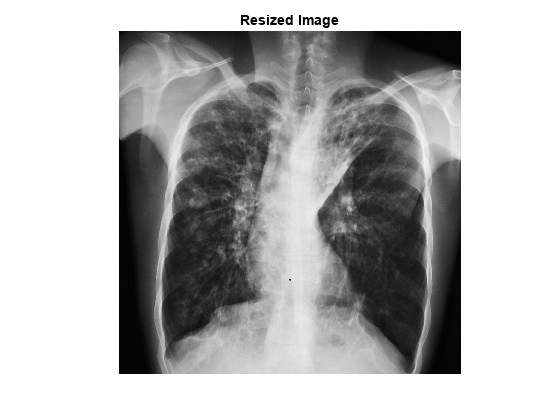

r_img = imresize(img, [1000, 1000]); % Resize image to standard size
imshow(r_img);
title('Resized Image');

**Step 3. **Determine the Color Type data of the original image. Convert to grayscale if the original image is RGB. 

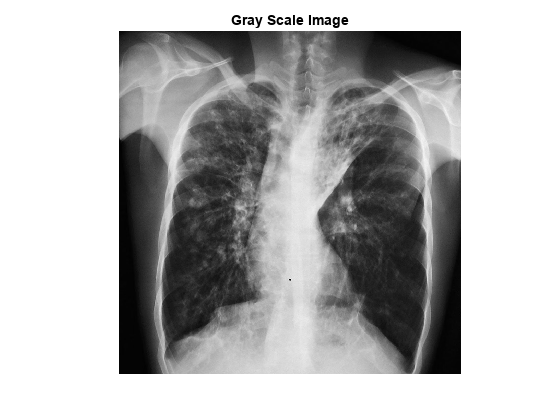

ColorType = imfinfo(I).ColorType; % Determines the Color Type data of the image. 

if ColorType == "truecolor"  % Sets up condition if the original image is RGB based it will convert it to grayscale
    bimg = rgb2gray(r_img);  % Convert RGB images to grayscale, store in new variable to binarizing
    imshow(bimg);
    title('Gray Scale Image');
else
    bimg = r_img; % If the image is already grayscale, it will not be converted.
    imshow(bimg);
    title('Gray Scale Image'); 
end

**Step 4.** Convert the image to a binary image using threshold values.

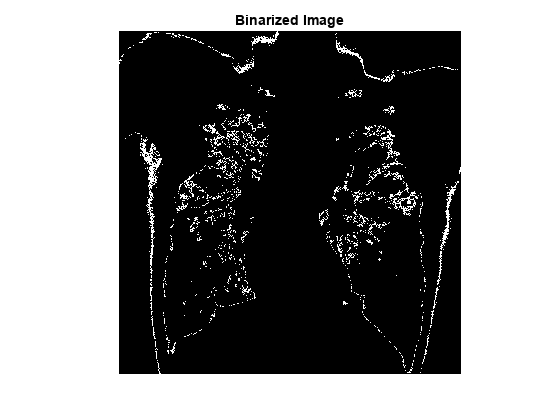

bimg(bimg>70) = 0;      % Create an upper limit for intensity, make the values above this black. 
bimg(bimg<63) = 0;      % Create an lower limit for intensity, make the values below this black. 
bimg(bimg>=63 & bimg<=70) = 255; % Everything inside these limits becomes white.

imshow(bimg);
title('Binarized Image');

**Step 5.** Create an overlay on the original image to show the detected mucus regions. 

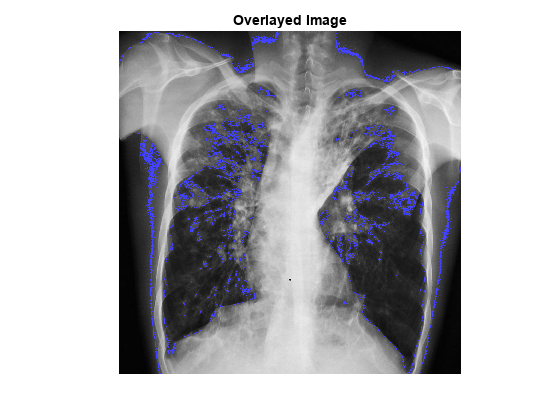

new = r_img; % Create a new image identical to the resized image.
[R, C] = size(bimg); % Determine size of image

for x = (1:1:R)
    for y = (1:1:C)
        if bimg(x,y) == 255
            new(x,y,3) = 255;  % Make all the white areas blue in the original image. 
        end
    end
end

imshow(new);
title('Overlayed Image');

**Step 6.** Crop region of interest. Calculate percentage of white pixels in region to quantify mucus in lungs. 

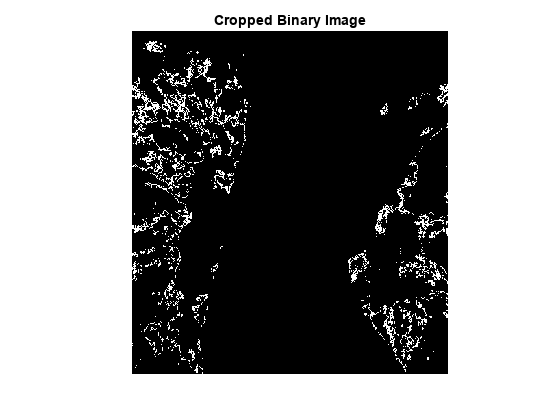

cropped_image = bimg(200:700, 270:730); % Creates a new image that is just the region of interest
area = numel(cropped_image);  % Calculates area of cropped image
imshow(cropped_image);
title('Cropped Binary Image');


whitepixels = length(find(cropped_image==255)); % Finds the amount of white pixels in cropped image.
percentage = (whitepixels/area) * 100;  % Determines the percentage of white pixels in cropped image. 


Step 7. Output to the user the percentage of mucus detected, and provide a prediction of if CF is present. 

fprintf('Percentage of lungs blocked by mucus: %.2f ', percentage);

Percentage of lungs blocked by mucus: 5.34 


if percentage > 2
    fprintf('Cystic Fibrosis Detected');
else
    fprintf('No Cystic Fibrosis Detected \nManual Review Needed.');
end

Cystic Fibrosis Detected